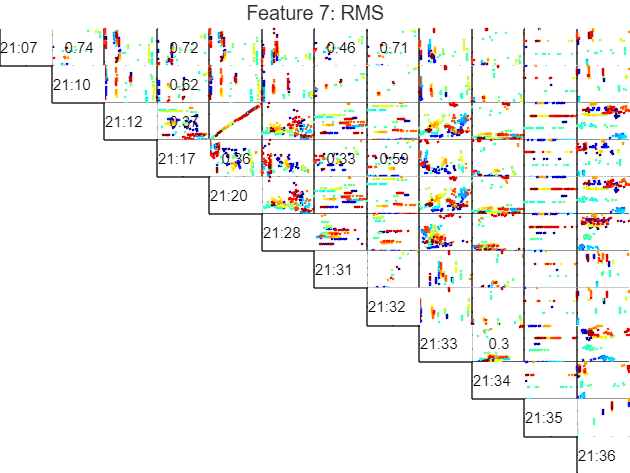

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
selectedFeature = 7; % RMS
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames);        

disp(num2str(R2, '%.2f  '));

0.00  0.74  0.29  0.72  0.29  0.01  0.46  0.71  0.01  0.00  0.00  0.00
0.00  0.00  0.18  0.62  0.18  0.00  0.81  1.00  0.00  0.04  0.00  0.01
0.00  0.00  0.00  0.37  1.00  0.03  0.01  0.17  0.11  0.00  0.17  0.12
0.00  0.00  0.00  0.00  0.36  0.00  0.33  0.59  0.09  0.02  0.07  0.03
0.00  0.00  0.00  0.00  0.00  0.04  0.02  0.17  0.11  0.00  0.16  0.12
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.28  0.30
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.06  0.10  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.05  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.30  0.08  0.03
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.91
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row 1
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectFeatures(selectedFeature, selectedSignal, featureArray, R2, upperR2, lowerR2);
disp(selectedSignalArray);

     1     2     4     7     8



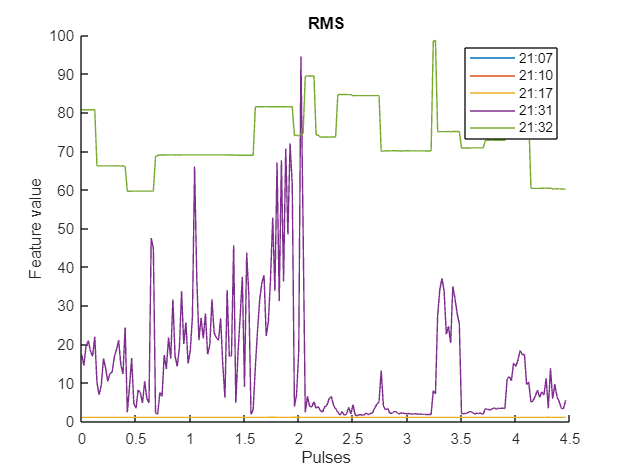

figure(); hold on;
leg = {numOfSelectedSignals};
for i = 1:numOfSelectedSignals
    plot(selectedSignalData{i});
    txtTemp = char(sensorNames(selectedSignalArray(i)));
    leg{i} = char(txtTemp(1:5));
end
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
legend(leg);

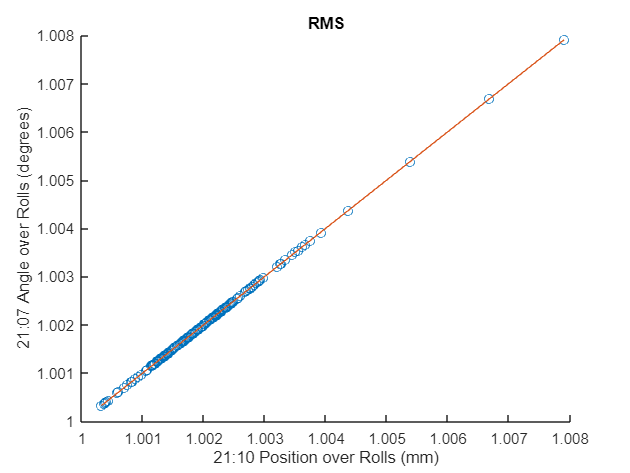

FIT = 99.90

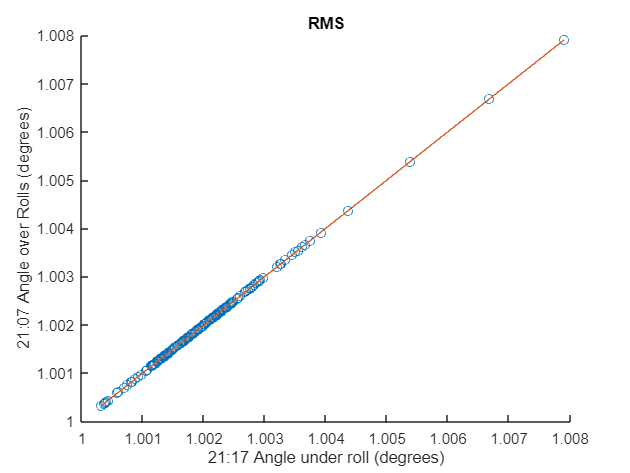

FIT = 99.97

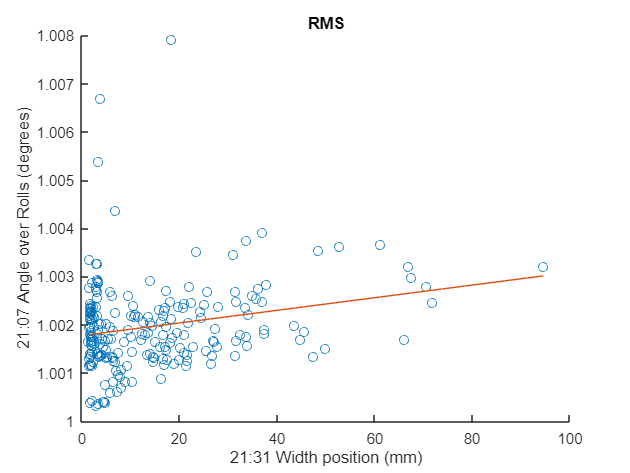

FIT = 2.65

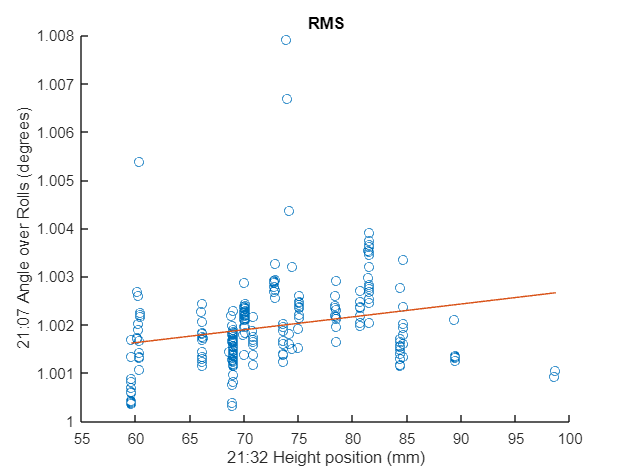

FIT = 2.79

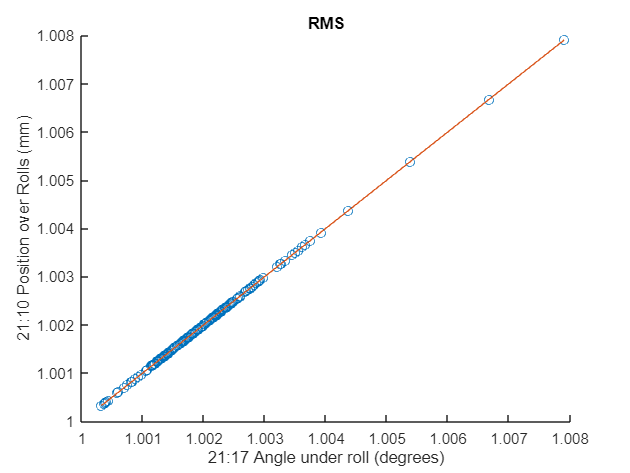

FIT = 99.94

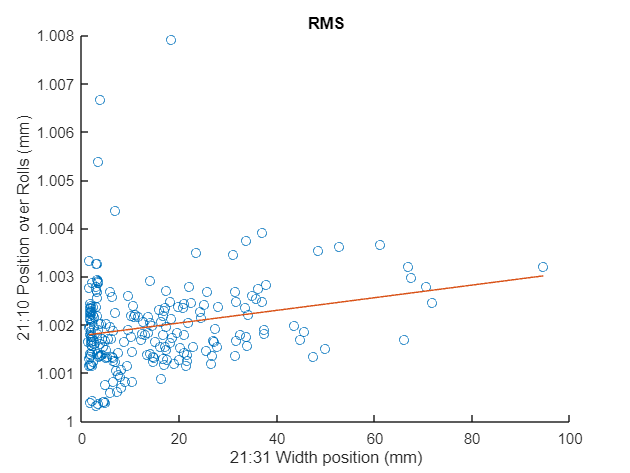

FIT = 2.66

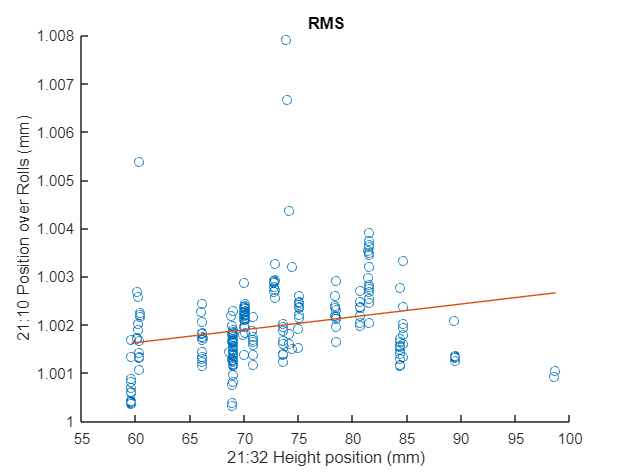

FIT = 2.80

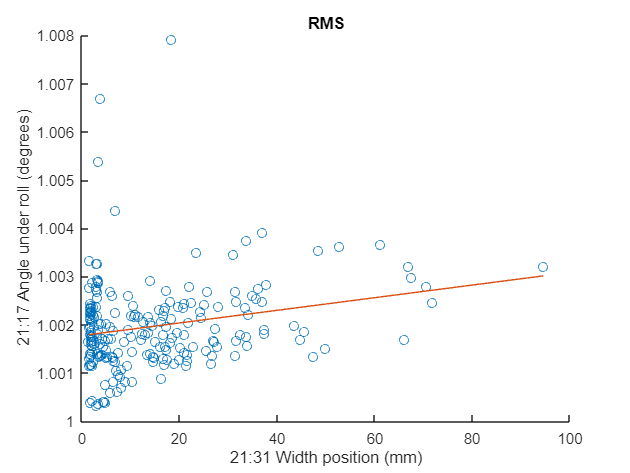

FIT = 2.65

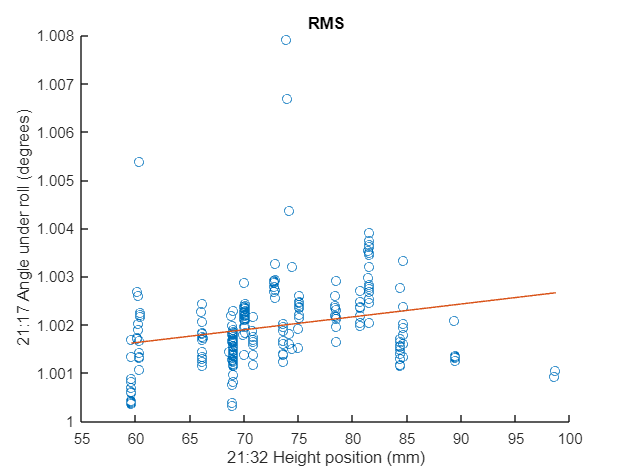

FIT = 2.80

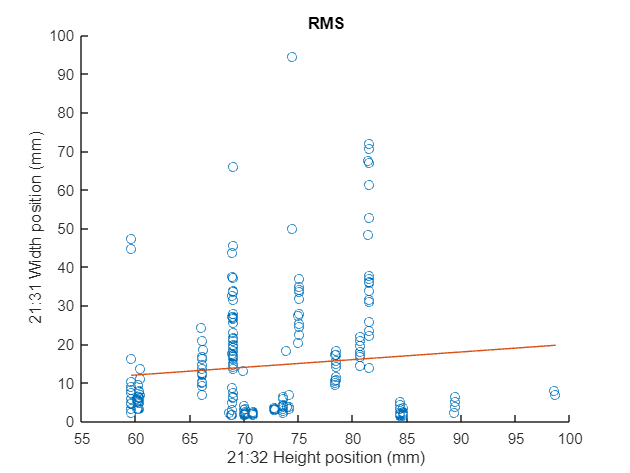

FIT = 0.50

for index1 = 1 : numOfSelectedSignals
    for index2 = index1 + 1 : numOfSelectedSignals
        fnPlotModel(selectedSignalData{index1}, ...
            selectedSignalData{index2}, ...
            FeatureNames(selectedFeature), ...
            sensorNames(selectedSignalArray(index1)), ...
            sensorNames(selectedSignalArray(index2)));
    end
end

1 2 3

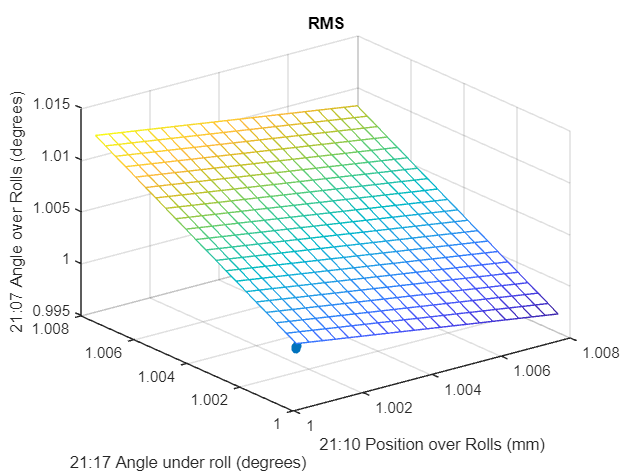

FIT = 45.756189

1 2 4

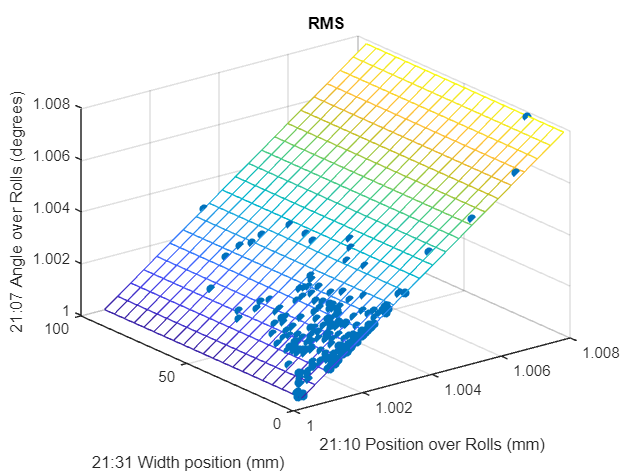

FIT = 99.911175

1 2 5

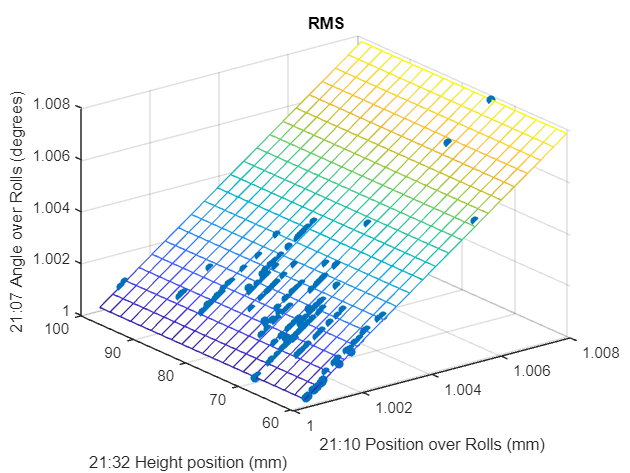

FIT = 99.905237

1 3 4

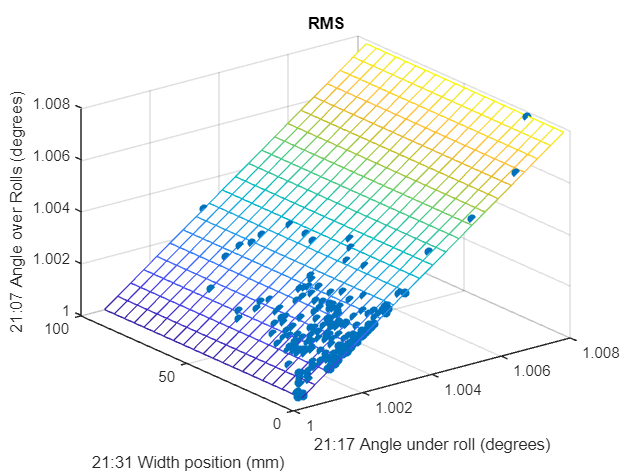

FIT = 99.970338

1 3 5

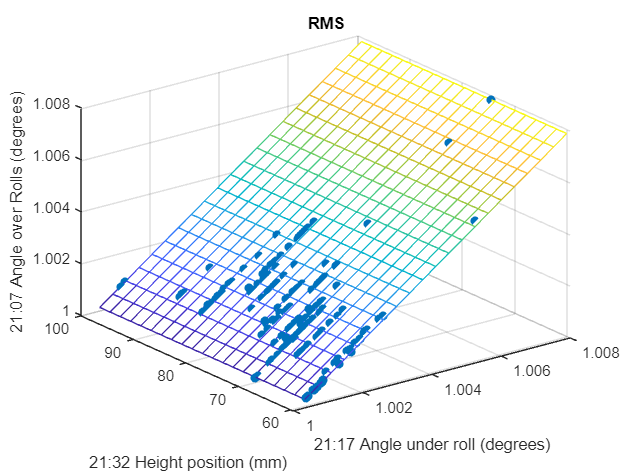

FIT = 99.968360

1 4 5

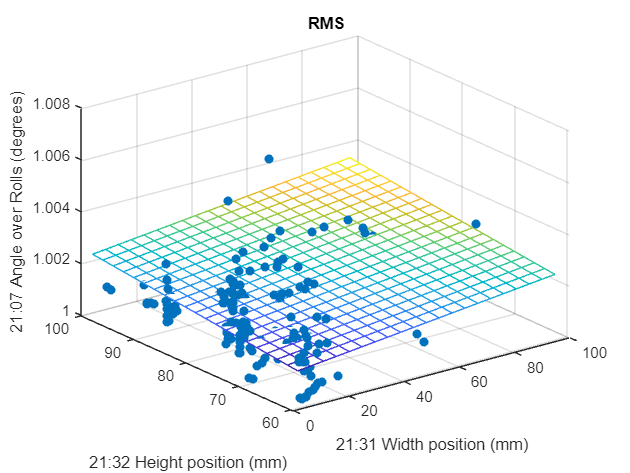

FIT = 5.006389

if numOfSelectedSignals > 2
    for index1 = 2 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            fprintf("%i %i %i", 1, index1, index2);
            Y_est = fnPlotModel3D( ...
                selectedSignalData{1}, ...
                selectedSignalData{index1}, ...
                selectedSignalData{index2}, ...
                FeatureNames(selectedFeature), ...
                sensorNames(selectedSignalArray(1)), ...
                sensorNames(selectedSignalArray(index1)), ...
                sensorNames(selectedSignalArray(index2)));
        end
    end
end